# Figure S2C

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';


load([dataDir filesep 'A039_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 16×6 cell array
    {'SU01 DOX TAK'   }    {[1 2]}    {[2 3]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'SU01 DOX DMSO'  }    {[3 4]}    {[2 3]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'SU01 DMSO DMSO' }    {[5 6]}    {[2 3]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'SU01 DMSO TAK'  }    {[7 8]}    {[2 3]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'S02 DOX TAK'    }    {[1 2]}    {[4 5]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'S02 DOX DMSO'   }    {[3 4]}    {[4 5]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'S02 DMSO DMSO'  }    {[5 6]}    {[4 5]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'S02 DMSO TAK'   }    {[7 8]}    {[4 5]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'SU03 DOX TAK'   }    {[1 2]}    {[6 7]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'SU03 DOX DMSO'  }    {[3 4]}    {[6 7]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'SU03 DMSO DMSO' }    {[5 6]}    {[6 7]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'SU03 DMSO TAK'  }    {[7 8]}    {[6 7]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'SU04 


 framesPerHr = 60/12;
 frameEdU = 0;
 timeStart = 0;
 folding =5;
 numFrames = size(S(1).area,2);
 xFrames = 1:numFrames;
 xTime = (xFrames-1)./framesPerHr;

 times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
 [S.POI_time] = times{:};

 for i = 1:length(S)
 
   S(i).POI_realtime = S(i).POI/framesPerHr;
   
 end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcGate = false(length(dat.POI(:,1)),1);
    dbf4Gate = false(length(dat.POI(:,1)),1);
    dbf4level = NaN*ones(length(dat.POI(:,1)),1);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 5 & dat.POI(n,1) + 7 < numFrames
            apcGate(n) = dat.apcAreaNorm(n,dat.POI(n,1) - 5) > .4 & ...
                dat.apcAreaNorm(n,dat.POI(n,1) +7) < .1 ;
        end

         if dat.POI(n,2) > 1 * framesPerHr & dat.POI(n,2) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcNormM(n,dat.POI(n,2) + [-1* framesPerHr: -.5* framesPerHr] )) < .2 & ...
                nanmean(dat.apcNormM(n,dat.POI(n,2) + [round(.5* framesPerHr): 1* framesPerHr] )) > .1;
         end

        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            dbf4Gate(n) = nanmean(dat.sigNorm(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .9 & ...
              nanmean(dat.sigNorm(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] ))< 1;
           
        end

    end
    S(i).apcGate = apcGate;
   S(i).dbf4Gate = dbf4Gate;
    S(i).dbf4level = dbf4level;
     S(i).apcExpressGate = apcExpressGate;
end

colors = [.8 .4 0;.4 .4 .8;.6 .8 .1;.333 .302 .541; 1 .831 0; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
 conds = [14 2];
figure('units','inches','position',[0 0 4 4]);
hold on
POI_align = 1;
timeGate = [0 100];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1)  &... ; %;&...
    S(conds(i)).dbf4Gate ;
  
sum(inds)
    ydata = data.sigNorm(inds,:);
    POI = data.POI(inds,POI_align) ;



        [frames, medSig, semCRL] =get_median_trace(ydata,POI,1);
        plot((frames)/framesPerHr,medSig,'LineWidth',2, 'Color',colors(i,:));
end

ans = 562

ans = 5730

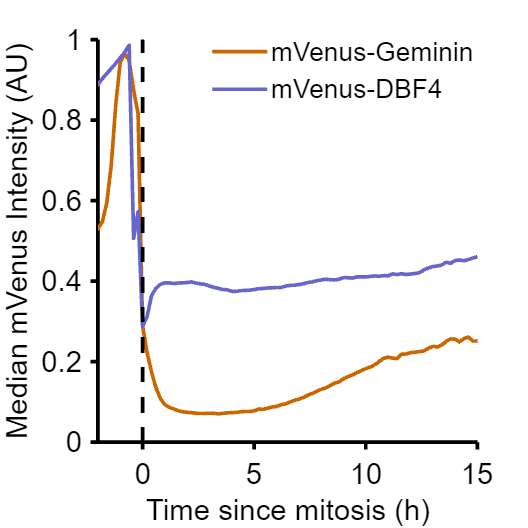


ylabel({'Median mVenus Intensity (AU)'});xlabel('Time since mitosis (h)');
legend('mVenus-Geminin','mVenus-DBF4','Location', 'northeast');
legend('boxoff')
legend("Position", [0.4401,0.78941,0.42188,0.15365])
xlim([-2 15]); 
ylim([0 1]);

 vline(0,'k--')

 % print_pdf(['fig_S2Ci'])



conds = [14 2];
figure('units','inches','position',[0 0 4 4]);
hold on
POI_align = 1;

for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1)  &... ; %;&...
    S(conds(i)).dbf4Gate ;
   
sum(inds)
    ydata = data.apcNormM(inds,:);
    POI = data.POI(inds,POI_align) ;



        [frames, medSig, semCRL] =get_median_trace(ydata,POI,1);
        plot((frames)/framesPerHr,medSig,'LineWidth',2, 'Color',colors(i,:));
end

ans = 562

ans = 5730

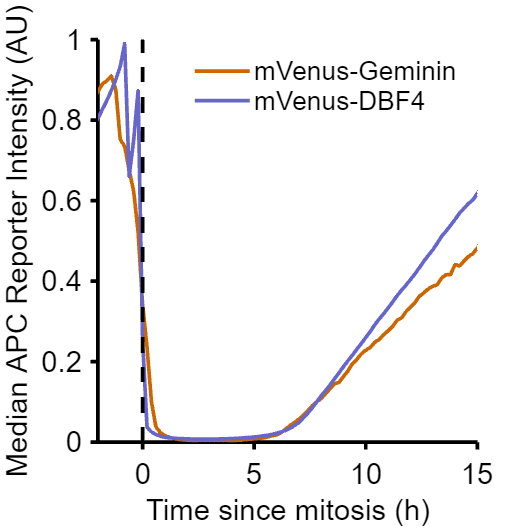


ylabel({'Median APC Reporter Intensity (AU)'});xlabel('Time since mitosis (h)');
legend('mVenus-Geminin','mVenus-DBF4','Location', 'northeast');
legend('boxoff')
xlim([-2 15]); 
ylim([0 1]);

 vline(0,'k--')

 % print_pdf(['Fig_S2Cii.pdf'])
